clc; clear; close all;

# Load 1D-FC Data

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5))

f = function_handle with value:
    @(x,y)4+(1+x.^2+y.^2).*(sin(2.5*pi*x-0.5)+cos(2*pi*y-0.5))


l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

C = 27;
d = 6;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

# Constructing Boundary Patch

## C2 Patch

Needs l(theta) data, the corners on the boundary in terms of theta, and function values on mesh

n_C2 = 20;
n_S_h = 20;
h_S = 0.027;

C2_patch = construct_C2_patch(f, 0.4, 2*pi-0.4, 0, n_C2, n_C2); % data associated with patch

[X, Y] = C2_patch.xy_mesh();
figure;
scatter(X(:), Y(:));
hold on;

## S Patch

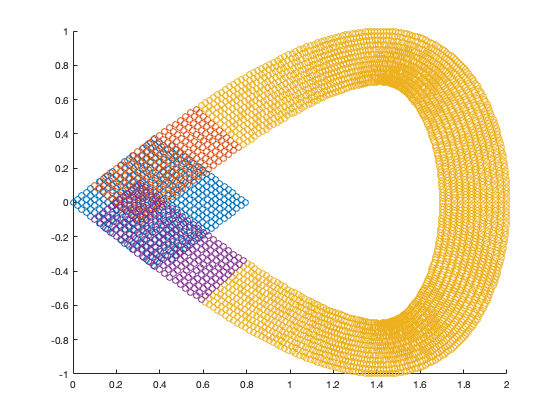

window_patch_xi = construct_S_patch(f, 0.1, 0.6, h_S, n_S_h, d+5);
window_patch_eta = construct_S_patch(f, 2*pi-0.1, 2*pi-0.6, h_S, n_S_h, d+5);
S_patch = construct_S_patch(f, 0.6, 2*pi-0.6, h_S, 255, d+5);

[X, Y] = window_patch_eta.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = S_patch.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = window_patch_xi.xy_mesh();
scatter(X(:), Y(:))


[C2_norm, xi_norm, eta_norm] = C2_patch.compute_phi_normalization(window_patch_xi, window_patch_eta);

# FC on C2 Patch and S Patch

Assumes we know what type the patches are, if not, we can simply add another entry that is enumeration of the patch types

% creates patch with data, including partition of unity
C2_fcont_patch = C2_patch.FC(C, d, A, Q, C2_norm);
window_fcont_patch_xi = window_patch_xi.FC(C, d, A, Q, xi_norm);
window_fcont_patch_eta = window_patch_eta.FC(C, d, A, Q, eta_norm);
S_fcont_patch = S_patch.FC(C, d, A, Q, nan);


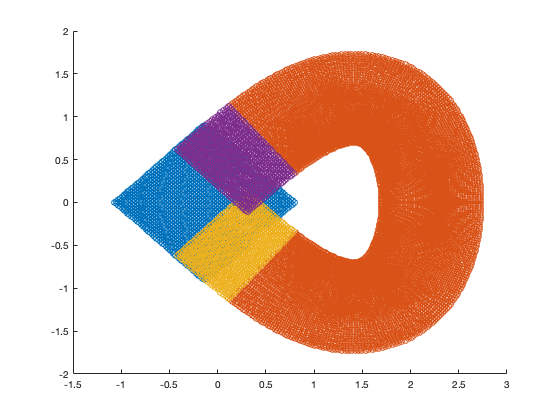

%% Image and boundary of each patch
[X_C2, Y_C2] = C2_fcont_patch.xy_mesh();
[X_S, Y_S] = S_fcont_patch.xy_mesh();
[X_xi, Y_xi] = window_fcont_patch_xi.xy_mesh();
[X_eta, Y_eta] = window_fcont_patch_eta.xy_mesh();
figure;
scatter(X_C2(:), Y_C2(:));
hold on;
scatter(X_S(:), Y_S(:));
scatter(X_xi(:), Y_xi(:));
scatter(X_eta(:), Y_eta(:));

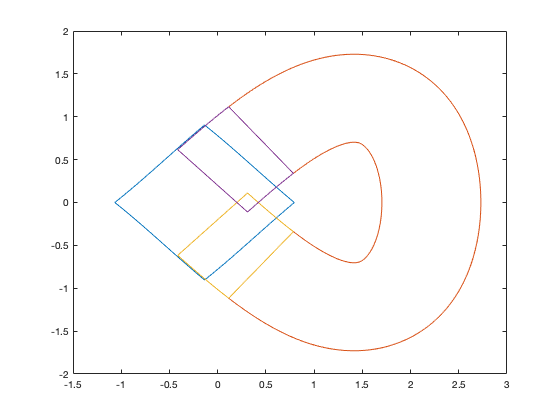


[bound_X, bound_Y] = C2_fcont_patch.boundary_mesh_xy();
figure;
plot(bound_X, bound_Y)
hold on;
[bound_X, bound_Y] = S_fcont_patch.boundary_mesh_xy();
plot(bound_X, bound_Y)
[bound_X, bound_Y] = window_fcont_patch_xi.boundary_mesh_xy();
plot(bound_X, bound_Y)
[bound_X, bound_Y] = window_fcont_patch_eta.boundary_mesh_xy();
plot(bound_X, bound_Y)

R_x_bounds = [C2_fcont_patch.x_min, S_fcont_patch.x_max]

R_x_bounds =    -1.0669    2.7290


R_y_bounds = [S_fcont_patch.y_min, S_fcont_patch.y_max]

R_y_bounds =    -1.7290    1.7290



h_R = 0.04;
x_mesh_R = transpose(R_x_bounds(1):h_R:ceil(R_x_bounds(2)/h_R)*h_R);
y_mesh_R = transpose(R_y_bounds(1):h_R:ceil(R_y_bounds(2)/h_R)*h_R);

ceil(R_x_bounds(2)/h_R)*h_R

ans = 2.7600


n_x = length(x_mesh_R);
n_y = length(y_mesh_R);

[R_X, R_Y] = meshgrid(x_mesh_R, y_mesh_R);

% Precomputed DAta - interior masks, patch masks, proximity map for each
% patch

% computes mask for points on interior
theta_mesh = transpose(linspace(0, 2*pi, 100));
boundary_XY = l_theta(theta_mesh);
in_interior = inpolygon(R_X, R_Y, boundary_XY(:, 1), boundary_XY(:, 2));

% % computes mask for points in patch that aren't on interior
% [bound_C2_X, bound_C2_Y] = C2_fcont_patch.boundary_mesh_xy();
% in_C2 = inpolygon(R_X, R_Y, bound_C2_X, bound_C2_Y) & ~in_interior;
% 
% [bound_S_X, bound_S_Y] = S_fcont_patch.boundary_mesh_xy();
% in_S = inpolygon(R_X, R_Y, bound_S_X, bound_S_Y) & ~in_interior;
% 
% [bound_window_xi_X, bound_window_xi_Y] = window_fcont_patch_xi.boundary_mesh_xy();
% in_window_xi = inpolygon(R_X, R_Y, bound_window_xi_X, bound_window_xi_Y) & ~in_interior;
% 
% [bound_window_eta_X, bound_window_eta_Y] = window_fcont_patch_eta.boundary_mesh_xy();
% in_window_eta = inpolygon(R_X, R_Y, bound_window_eta_X, bound_window_eta_Y) & ~in_interior;
% 
% figure;
% scatter(R_X(in_interior), R_Y(in_interior))
% hold on;
% scatter(R_X(in_window_eta), R_Y(in_window_eta))
% scatter(R_X(in_window_xi), R_Y(in_window_xi))
% scatter(R_X(in_S), R_Y(in_S))
% scatter(R_X(in_C2), R_Y(in_C2))

% % computes proximity map
% C2_points_X = R_X(in_C2);
% C2_points_Y = R_Y(in_C2);
% 
% [XI, ETA] = C2_fcont_patch.xi_eta_mesh();
% [C2_X, C2_Y] = C2_fcont_patch.convert_to_XY(XI, ETA);
% 
% floor_C2_X = floor((C2_X-R_x_bounds(1))/h_R)*h_R + R_x_bounds(1);
% ceil_C2_X = ceil((C2_X-R_x_bounds(1))/h_R)*h_R + R_x_bounds(1);
% floor_C2_Y = floor((C2_Y-R_y_bounds(1))/h_R)*h_R + R_y_bounds(1);
% ceil_C2_Y = ceil((C2_Y-R_y_bounds(1))/h_R)*h_R + R_y_bounds(1);
% 
% P = containers.Map('KeyType', 'char', 'ValueType', 'any');
% for i = 1:length(C2_points_X)
%     P(mat2str([C2_points_X(i); C2_points_Y(i)])) = nan;
% end
% 
% for i = 1:size(C2_X, 1)
%     for j = 1:size(C2_X, 2)
%         neighbors = [floor_C2_X(i, j), floor_C2_X(i, j), ceil_C2_X(i, j), ceil_C2_X(i, j); floor_C2_Y(i, j), ceil_C2_Y(i, j), floor_C2_Y(i, j), ceil_C2_Y(i, j)];
%         for neighbor_i = 1:size(neighbors, 2)
%             neighbor = neighbors(:, neighbor_i);
%             str_neighbor = mat2str(neighbor);
%             
%             if isKey(P, str_neighbor)
%                 if isnan(P(str_neighbor))
%                     [xi, eta, converged] = C2_fcont_patch.inverse_M_p(neighbor(1), neighbor(2), [XI(i, j); ETA(i, j)]);
%                     if converged
%                         P(str_neighbor) = [xi; eta];
%                     else
%                         warning("Nonconvergence in interopolation")
%                     end
%                 end
%             end
%         end
%     end
% end
%             
% for key = keys(P)
%     if isnan(P(key{1}))
%         pnt = eval(key{1});
%         neighboridxs = [1 -1 0 0; 0 0 -1 1];
%         for neighboridx_i = 1:size(neighboridxs, 2)
%             neighboridx = neighboridxs(:, neighboridx_i);
%             neighbor = pnt + neighboridx * h_R;
%             str_neighbor = mat2str(neighbor);
%             if isKey(P, str_neighbor) && ~any(isnan((P(str_neighbor))))
%                 [xi, eta, converged] = C2_fcont_patch.inverse_M_p(pnt(1), pnt(2), P(str_neighbor));
%                 if converged
%                     P(key{1}) = [xi; eta];
%                 else
%                     warning("Nonconvergence in interpolation")
%                 end
%                 break;
%             end
%         end
%     end
% end
% 
% max_norm = 0;
% for key = keys(P)
%     cartesian_point = eval(key{1});
%     corner_point = P(key{1});
%     corner_point = C2_fcont_patch.M_p(corner_point(1), corner_point(2))';
%     
%     if norm(cartesian_point - corner_point) > max_norm
%         max_norm = norm(cartesian_point - corner_point);
%     end
% end
% max_norm

% f_R_C2 = zeros(size(C2_points_X));
% for i = 1:length(C2_points_X)
%     xi_eta_point = P(mat2str([C2_points_X(i); C2_points_Y(i)]));
%     [f_R_C2(i), in_range] = C2_fcont_patch.locally_compute(xi_eta_point(1), xi_eta_point(2), d+3);
%     if ~in_range
%         disp('huh')
%     end
% end
% 
% figure;
% scatter3(C2_points_X, C2_points_Y, f_R_C2)

# OOP Approach

patches = {C2_fcont_patch, S_fcont_patch, window_fcont_patch_xi, window_fcont_patch_eta};

R = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), h_R, boundary_XY(:, 1), boundary_XY(:, 2))

R =   R_cartesian_mesh_obj with properties:

        x_start: -1.0669
          x_end: 2.7331
        y_start: -1.7290
          y_end: 1.7510
              h: 0.0400
            n_x: 96
            n_y: 88
         x_mesh: [96×1 double]
         y_mesh: [88×1 double]
            R_X: [88×96 double]
            R_Y: [88×96 double]
         R_idxs: [88×96 double]
     boundary_X: [100×1 double]
     boundary_Y: [100×1 double]
    in_interior: [88×96 logical]
            f_R: [88×96 double]
      fc_coeffs: []



for patch = patches
    R.interpolate_patch(patch{1}, d+3)
end
R.fill_interior(f);

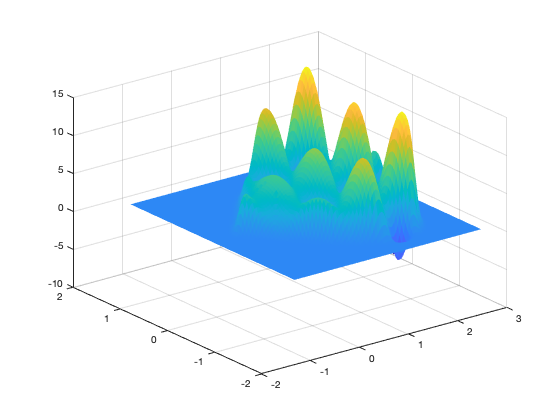


figure;
s = surf(R.R_X, R.R_Y, R.f_R);
s.EdgeColor = 'none';

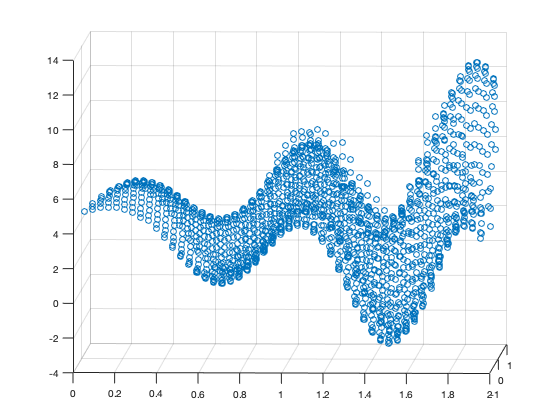


figure;
s = scatter3(R.R_X(in_interior), R.R_Y(in_interior), f(R.R_X(in_interior), R.R_Y(in_interior)));

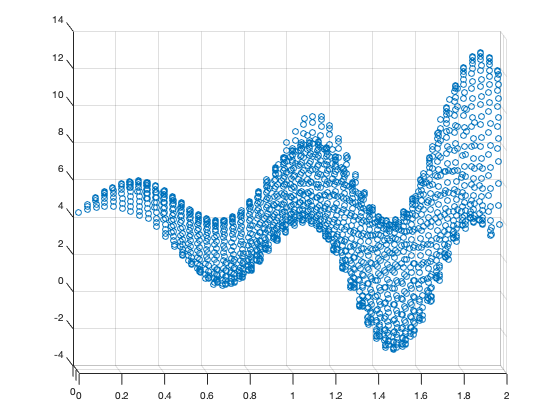


figure;
scatter3(R_X(in_interior), R_Y(in_interior), R.f_R(in_interior))


R_X

R_X =    -1.0669   -1.0269   -0.9869   -0.9469   -0.9069   -0.8669   -0.8269   -0.7869   -0.7469   -0.7069   -0.6669   -0.6269   -0.5869   -0.5469   -0.5069   -0.4669   -0.4269   -0.3869   -0.3469   -0.3069   -0.2669   -0.2269   -0.1869   -0.1469   -0.1069   -0.0669   -0.0269    0.0131    0.0531    0.0931    0.1331    0.1731    0.2131    0.2531    0.2931    0.3331    0.3731    0.4131    0.4531    0.4931    0.5331    0.5731    0.6131    0.6531    0.6931    0.7331    0.7731    0.8131    0.8531    0.8931
   -1.0669   -1.0269   -0.9869   -0.9469   -0.9069   -0.8669   -0.8269   -0.7869   -0.7469   -0.7069   -0.6669   -0.6269   -0.5869   -0.5469   -0.5069   -0.4669   -0.4269   -0.3869   -0.3469   -0.3069   -0.2669   -0.2269   -0.1869   -0.1469   -0.1069   -0.0669   -0.0269    0.0131    0.0531    0.0931    0.1331    0.1731    0.2131    0.2531    0.2931    0.3331    0.3731    0.4131    0.4531    0.4931    0.5331    0.5731    0.6131    0.6531    0.6931    0.7331    0.7731    0.8131    0.8531   

R.R_X

ans =    -1.0669   -1.0269   -0.9869   -0.9469   -0.9069   -0.8669   -0.8269   -0.7869   -0.7469   -0.7069   -0.6669   -0.6269   -0.5869   -0.5469   -0.5069   -0.4669   -0.4269   -0.3869   -0.3469   -0.3069   -0.2669   -0.2269   -0.1869   -0.1469   -0.1069   -0.0669   -0.0269    0.0131    0.0531    0.0931    0.1331    0.1731    0.2131    0.2531    0.2931    0.3331    0.3731    0.4131    0.4531    0.4931    0.5331    0.5731    0.6131    0.6531    0.6931    0.7331    0.7731    0.8131    0.8531    0.8931
   -1.0669   -1.0269   -0.9869   -0.9469   -0.9069   -0.8669   -0.8269   -0.7869   -0.7469   -0.7069   -0.6669   -0.6269   -0.5869   -0.5469   -0.5069   -0.4669   -0.4269   -0.3869   -0.3469   -0.3069   -0.2669   -0.2269   -0.1869   -0.1469   -0.1069   -0.0669   -0.0269    0.0131    0.0531    0.0931    0.1331    0.1731    0.2131    0.2531    0.2931    0.3331    0.3731    0.4131    0.4531    0.4931    0.5331    0.5731    0.6131    0.6531    0.6931    0.7331    0.7731    0.8131    0.8531   

R.compute_fc_coeffs()
[X_err, Y_err, f_err, err_interior_idx] = R.ifft_interpolation(R.h * 0.5);
max(abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx))))

ans = 0.2325

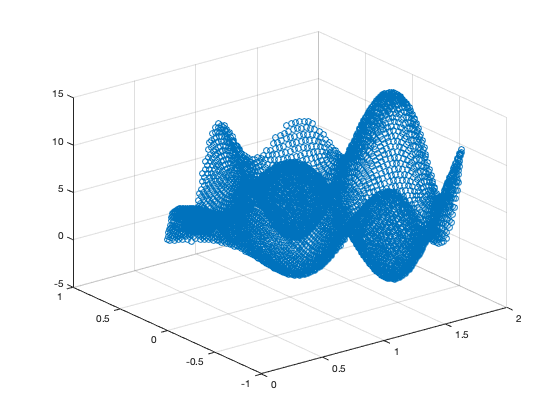


figure;
scatter3(X_err(err_interior_idx), Y_err(err_interior_idx), f_err(err_interior_idx))

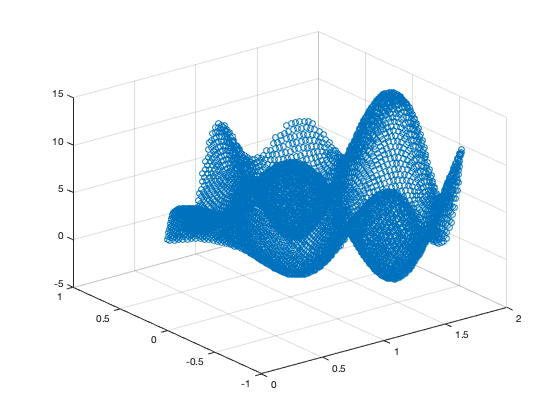


figure;
scatter3(X_err(err_interior_idx), Y_err(err_interior_idx), f(X_err(err_interior_idx), Y_err(err_interior_idx)))

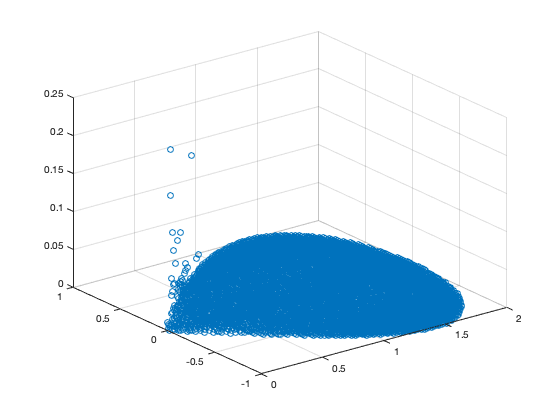


figure;
scatter3(X_err(err_interior_idx), Y_err(err_interior_idx), abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx))))

% figure;
% scatter(R_X(in_S), R_Y(in_S))
% hold on;
% [X, Y] = S_fcont_patch.xy_mesh();
% scatter(X(:), Y(:))

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end